1.	从dataset.xlsx 中，利用readmatrix将close_price、market_capital导入MATLAB

close_price = readmatrix("dataset.xlsx",'Sheet',2,'Range','B2:AI116');
market_cap = readmatrix("dataset.xlsx",'Sheet',4,'Range','B2:AI116');


2.	根据close_price，计算收益率数据，并导出到dataset.xlsx中新的表中，命名为

ret = log(close_price(2:end,:)./close_price(1:end-1,:));
% ret = close_price(2:end,:)./close_price(1:end-1,:) - 1;
writematrix(ret,"dataset.xlsx",'Sheet','return');

3.	计算收益率数据的下列统计量：

1	均值

retstats.mean_ret = mean(ret);

2	样本标准差

retstats.std_ret = std(ret);

3	样本方差

retstats.var_ret = var(ret);

4	偏度

retstats.skew_ret = skewness(ret);

5	峰度

retstats.kurt_ret=  kurtosis(ret);

6	变异系数

retstats.CV_ret = retstats.std_ret./retstats.mean_ret;

4.	计算market_capital数据的下列统计量，并基于数据1和数据11绘制散点图，标注x轴和y轴的名称：

7	最大值和最小值

capstats.min_cap = min(market_cap); capstats.max_cap = max(market_cap);

8	极差

capstats.range_cap = range(market_cap);

9	中位数

capstats.mid_cap = median(market_cap);

10	原点矩

capstats.ori_mmt_cap_1 = mean(market_cap);
capstats.ori_mmt_cap_2 = mean(market_cap.^2);


11	中心矩

capstats.mmt_cap_1 = moment(market_cap,1);
capstats.mmt_cap_2 = moment(market_cap,2);

5.	利用cov计算收益率数据的协方差矩阵，利用imagesc进行可视化，并标注图标题：“协方差矩阵”

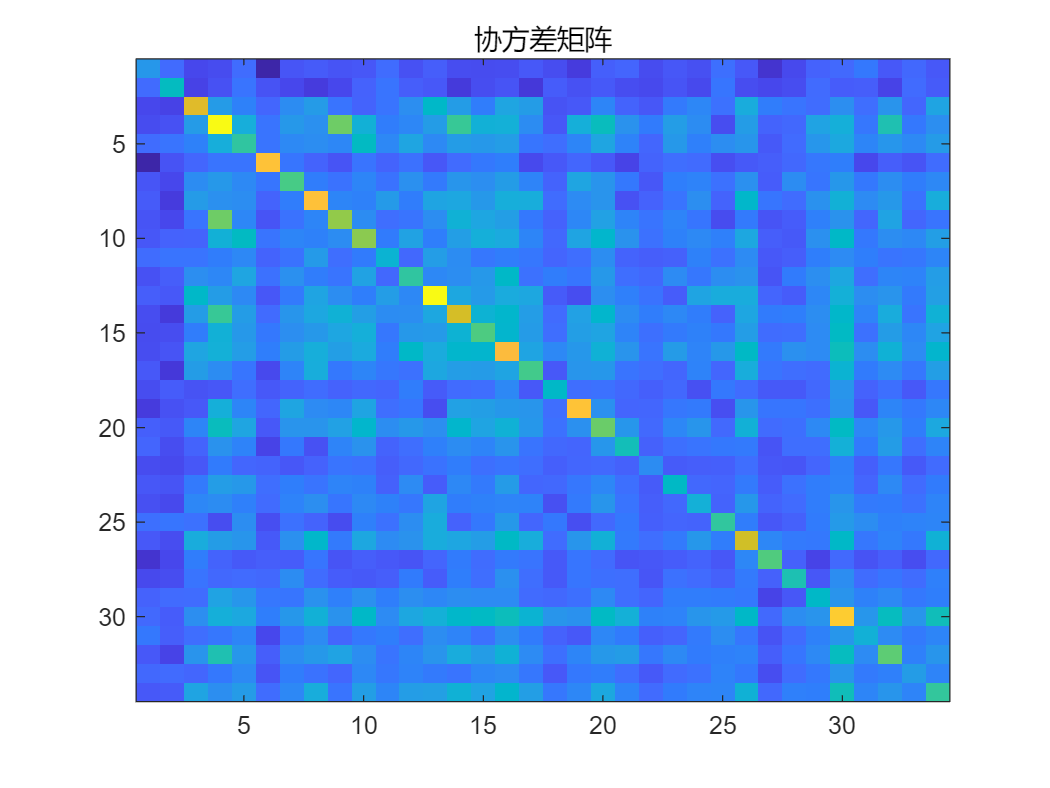

retstats.cov_ret = cov(ret);
figure
imagesc(retstats.cov_ret);
title('协方差矩阵')

6.	利用corrcoef计算收益率数据的相关系数矩阵，利用imagesc进行可视化，并标注图标题：“相关性矩阵”

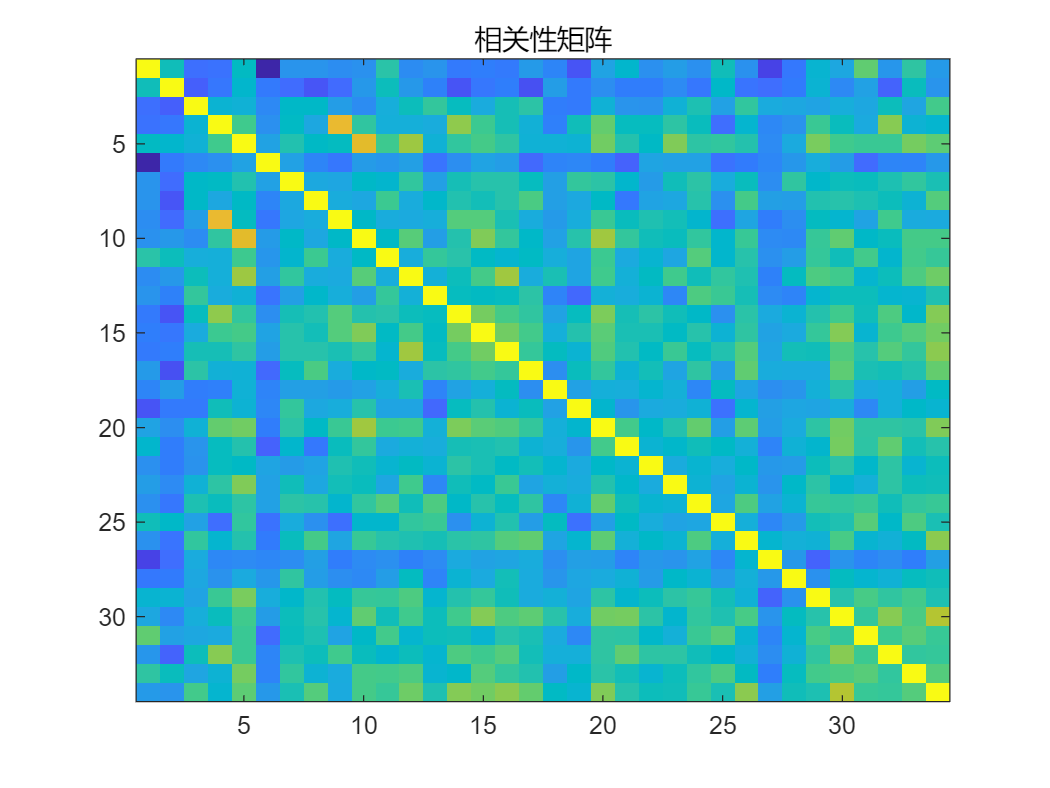

retstats.corr_ret = corrcoef(ret);
figure
imagesc(retstats.corr_ret);
title('相关性矩阵')

7.	利用ecdf和ecdfhist函数给出收益率数据的频率直方图，并利用normpdf绘制概率密度函数，标注x轴名称：“收益率分布”，添加标注框：[‘频率直方图‘, ’正态分布曲线’]。

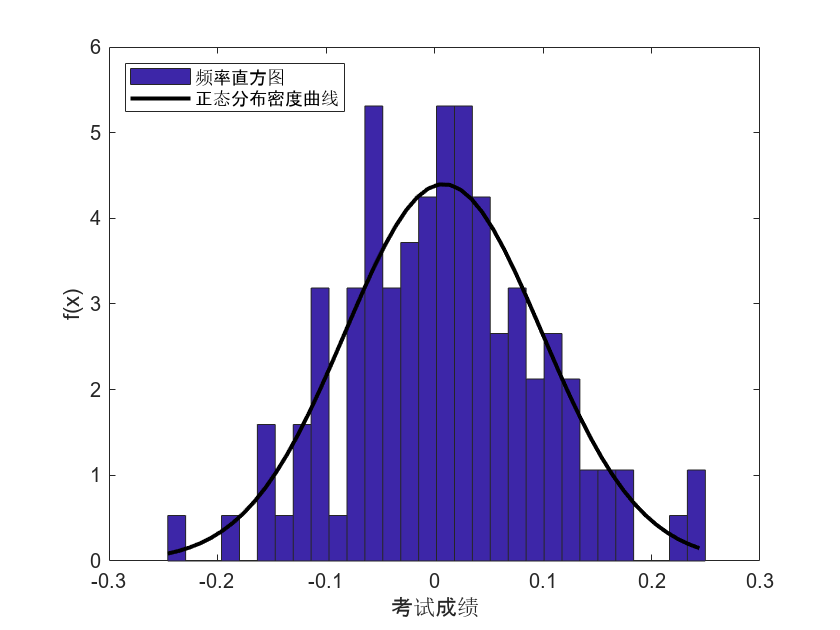

pick_i = 1;%input('please give a number(1~34):');
pick_j = 2;%input('please give a number(1~34):');
figure;
ret_i = ret(:,pick_i);
ret_j = ret(:,pick_j);
[f, xc] = ecdf(ret_i);
ecdfhist(f, xc, 30);
xlabel('考试成绩');
ylabel('f(x)');
x = min(ret_i):.01:max(ret_i);
y = normpdf(x,mean(ret_i),std(ret_i));
hold on
plot(x,y,'k','LineWidth',2)
legend('频率直方图','正态分布密度曲线','Location','NorthWest');

8.	分别利用normplot、probplot、qqplot拟合收益率数据的分布

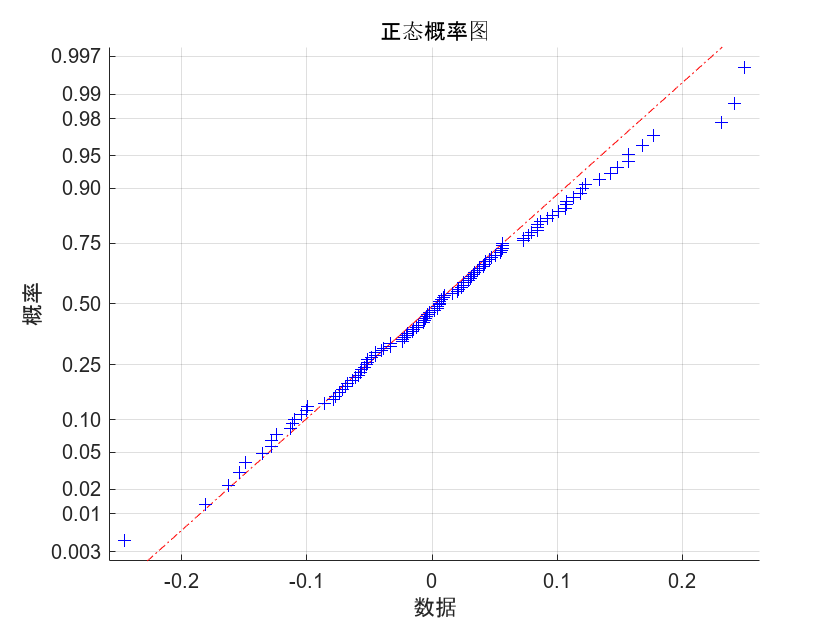

figure;
normplot(ret_i); 

%% p-p图

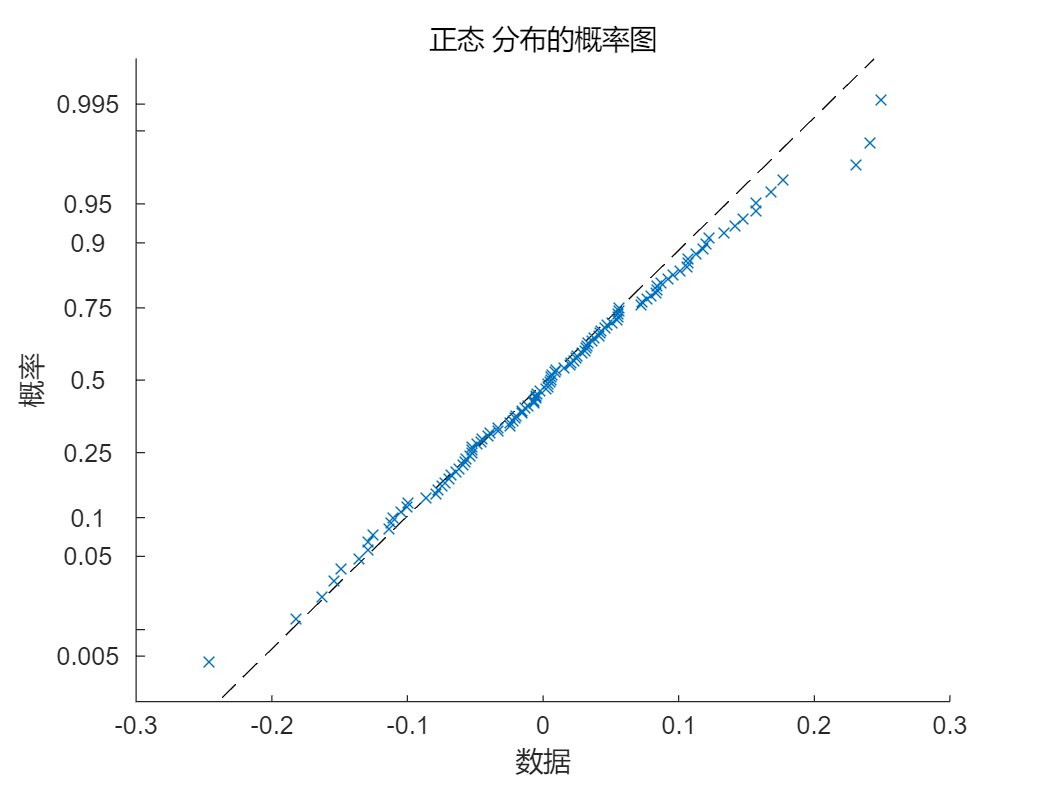

figure
probplot('normal',ret_i)

%% q-q图

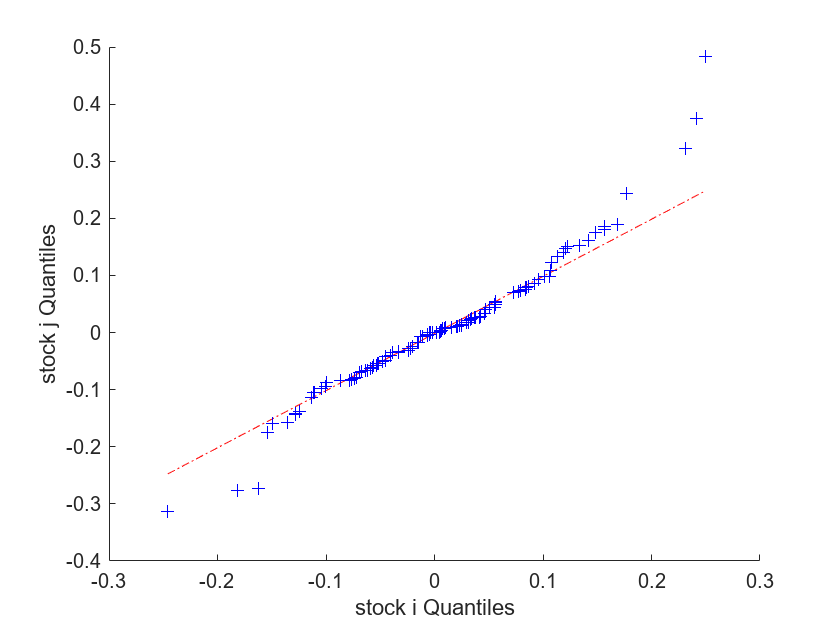

qqplot(ret_i,ret_j)
xlabel('stock i Quantiles');
ylabel('stock j Quantiles');

9.	利用readcell将Industry数据导入MATLAB

industry = readcell("dataset.xlsx","Sheet",1,"Range","B2:B35");

10.	利用tabulate函数统计行业分布，制作行业分布饼图

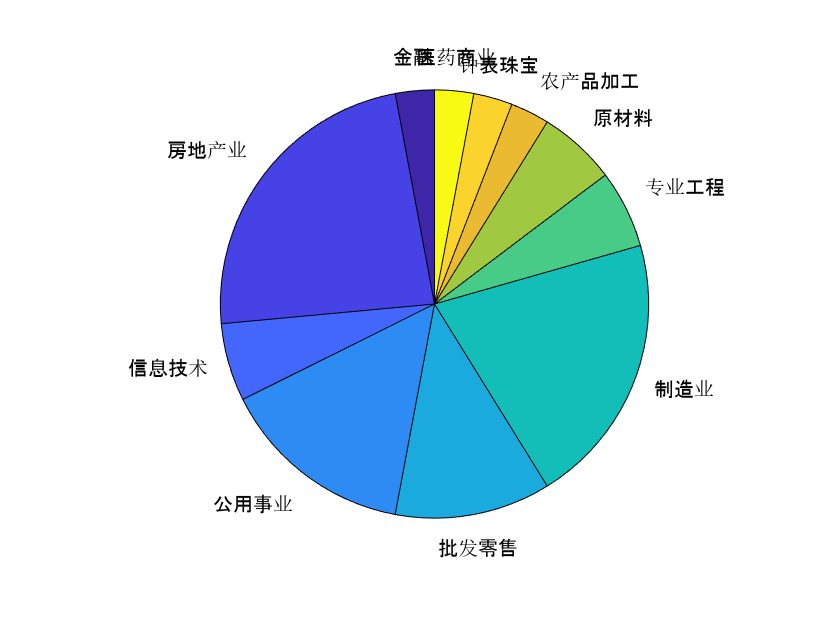

ind = tabulate(industry);
figure
nums = cell2mat(ind(:,2));
labels = ind(:,1);
pie(nums, labels)

11.	X = [‘For wisdom is a protection just as money is a protection, but the advantage of knowledge is this: Wisdom preserves the life of its owner.’]

利用HistRate函数统计上述字符串中，各字符出现的频数、频率和累积频率

% HistRate(X)